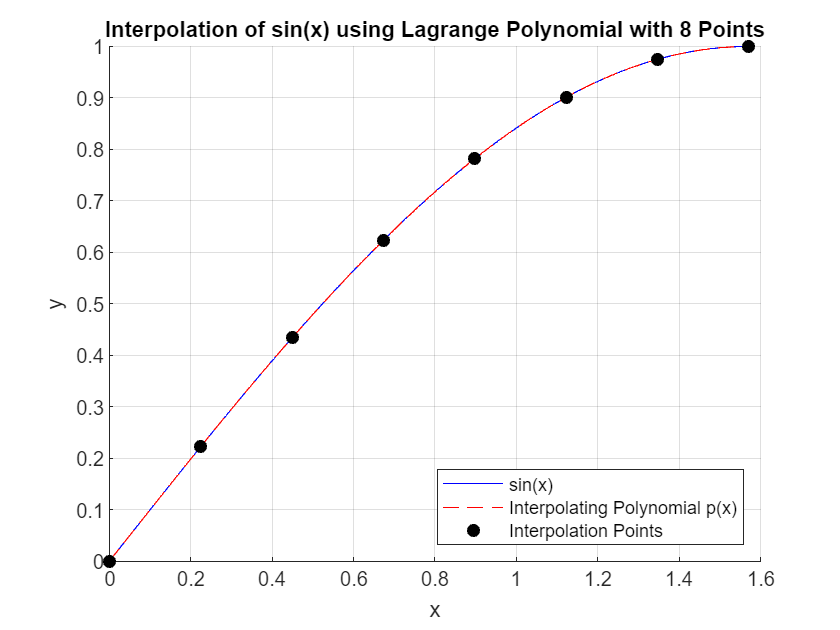

clc; clear; close all

% Define the function and interval
f = @(x) sin(x);
a = 0;
b = pi/2;

% Number of interpolation points (change this value to any number)
n_points = 8;

% Generate equally spaced interpolation points
x_points = linspace(a, b, n_points);
y_points = f(x_points);

% Define the x range for plotting
x = linspace(a, b, 400);
y = f(x);

% Initialize the interpolating polynomial
p = zeros(size(x));

% Calculate the Lagrange basis polynomials and construct the interpolating polynomial
for i = 1:n_points
    % Calculate the i-th Lagrange basis polynomial
    L_i = ones(size(x));
    for j = 1:n_points
        if j ~= i
            L_i = L_i .* (x - x_points(j)) / (x_points(i) - x_points(j));
        end
    end
    % Add the contribution of the i-th basis polynomial to the interpolating polynomial
    p = p + y_points(i) * L_i;
end

% Plot the original function and the interpolating polynomial
figure;
hold on;
plot(x, y, 'b-', 'DisplayName', 'sin(x)');
plot(x, p, 'r--', 'DisplayName', 'Interpolating Polynomial p(x)');
plot(x_points, y_points, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Interpolation Points');
xlabel('x');
ylabel('y');
title(['Interpolation of sin(x) using Lagrange Polynomial with ', num2str(n_points), ' Points']);
legend("Location","southeast")
legend show;
grid on;
hold off;

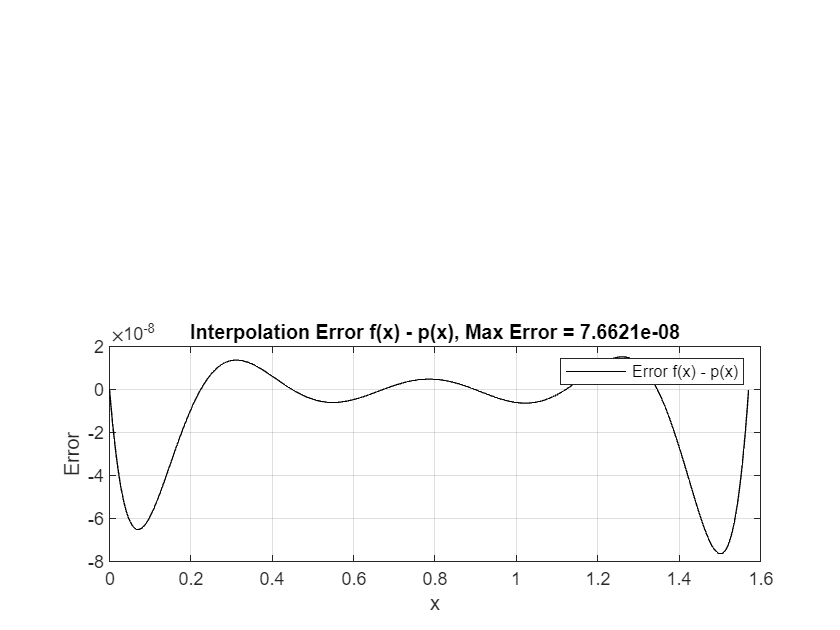

% Compute the interpolation error
error = y - p;
max_actual_error  = max(abs(error));

% Plot the interpolation error
subplot(2, 1, 2);
plot(x, error, 'k-', 'DisplayName', 'Error f(x) - p(x)');
xlabel('x');
ylabel('Error');
title(['Interpolation Error f(x) - p(x), Max Error = ', num2str(max_actual_error )]);
legend show;
grid on;

% Calculate the maximum error term
product_term = ones(size(x));
for i = 1:n_points
    product_term = product_term .* (x - x_points(i));
end
% Since the function is sin(x), the fourth derivative is sin(x) again
% The maximum value of sin(x) in [0, pi/2] is 1
max_f_derivative = 1;
factorial_term = factorial(n_points);
error_term = abs(product_term * max_f_derivative / factorial_term);

% Evaluate the maximum error estimate across the x range
max_error_estimate = max(error_term);

% Display the results
disp(['Maximum error estimate (upper bound) from Newton’s formula: ', num2str(max_error_estimate)]);

Maximum error estimate (upper bound) from Newton’s formula: 1.0213e-07


disp(['Actual maximum interpolation error: ', num2str(max_actual_error)]);

Actual maximum interpolation error: 7.6621e-08
